# Angoli Di Eulero

Una rappresentazione minima dell'orientamento di un corpo rigido nello spazio tridimensionale richiede esattamente tre parametri indipendenti. Questo deriva dal fatto che il gruppo speciale ortogonale **SO(m)**, che descrive le rotazioni nello spazio tridimensionale, ha dimensione $\frac{m(m-1)}{2}$. Per ottenere una rappresentazione minima, si possono utilizzare insiemi di tre angoli


$$\mathbf{\alpha }={\left(\begin{array}{ccc} \phi & \theta & \psi \end{array}\right)}^T$$


Noti come *angoli di Eulero*, che descrivono sequenze di rotazioni elementari intorno agli assi di un sistema di coordinate. Componendo tre rotazioni elementari consecutive, è possibile costruire una matrice di rotazione che rappresenta l'orientamento del corpo rigido. Affinché questa rappresentazione sia valida, è necessario che due rotazioni consecutive non avvengano intorno ad assi paralleli, altrimenti si perderebbe un grado di libertà.

Tra queste, tre tipi di terne sono particolarmente rilevanti:

- **Angoli ZXZ:** Prevedono delle rotazioni successive intorno agli assi: $Z$, $X^{\prime }$ (asse $X$ ruotato) e $Z^{\prime \prime }$ (asse $Z$ nuovamente ruotato)

- **Angoli ZXY:** Prevedono delle rotazioni successive intorno agli assi: $Z$, $X^{\prime }$ (asse $X$ ruotato) e $Y^{\prime \prime }$ (asse $Y$ nuovamente ruotato)

- **Angoli RPY:** Prevedono delle rotazioni intorno agli assi $Z$, $Y^{\prime }$ e $X^{\prime \prime }$

Per essere valida, una sequenza di rotazioni non deve avere due rotazioni consecutive attorno ad assi paralleli. Due delle convenzioni valide sono **ZXZ** e **ZXY**.

% Risoluzione percorso cartella funzioni ausiliarie Codici Matlab
if ~exist('Compute_DH_Transformations', 'file') || ~exist('Compute_Rotation_Matrix', 'file')
    candDirs = {pwd, fileparts(pwd)};
    try
        edFile = matlab.desktop.editor.getActiveFilename;
        candDirs = [candDirs, {fileparts(edFile), fileparts(fileparts(edFile))}];
    catch
    end
    for iCand = 1:numel(candDirs)
        cDir = candDirs{iCand};
        if isfolder(cDir) && (isfile(fullfile(cDir, 'Compute_DH_Transformations.m')) || isfile(fullfile(cDir, 'Compute_Rotation_Matrix.m')))
            addpath(cDir);
            break;
        end
    end
end
clc; clear; close all;

% Definizione Angoli Simbolici
syms phi theta psi real;

% Definzione Assi
x = [1; 0; 0];
y = [0; 1; 0];
z = [0; 0; 1];

## Rotazione ZXZ

Questa convenzione utilizza la seguente sequenza di rotazioni:

- Rotazione di un angolo $\phi$ attorno all'asse $Z$.

- Rotazione di un angolo $\theta$ attorno al nuovo asse $X^{\prime }$ (l'asse $X$ ruotato).

- Rotazione di un angolo $\psi$ attorno al nuovo asse $Z^{\prime \prime }$ (l'asse $Z$ nuovamente ruotato).

La matrice di rotazione complessiva è data dal prodotto delle singole matrici di rotazione. Quindi:

% ROTAZIONE ZXZ
% R_ZXZ = R_Z(phi) * R_X'(theta) * R_Z''(psi)

[RZ_Phi] = Compute_Rotation_Matrix(z, phi);
[RX_Theta] = Compute_Rotation_Matrix(x, theta);
[RZ_Psi] = Compute_Rotation_Matrix(z, psi);

RZXZ = RZ_Phi * RX_Theta * RZ_Psi;
RZXZ = simplify(RZXZ);

disp("Matrice Di Rotazione Simbolica R_ZXZ:");

Matrice Di Rotazione Simbolica R_ZXZ:


disp(RZXZ);

$$\left(\begin{array}{ccc} \cos\left(\varphi \right)\,\cos\left(\psi \right)-\cos\left(\theta \right)\,\sin\left(\varphi \right)\,\sin\left(\psi \right) & -\cos\left(\varphi \right)\,\sin\left(\psi \right)-\cos\left(\psi \right)\,\cos\left(\theta \right)\,\sin\left(\varphi \right) & \sin\left(\varphi \right)\,\sin\left(\theta \right)\\ \cos\left(\psi \right)\,\sin\left(\varphi \right)+\cos\left(\varphi \right)\,\cos\left(\theta \right)\,\sin\left(\psi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)\,\cos\left(\theta \right)-\sin\left(\varphi \right)\,\sin\left(\psi \right) & -\cos\left(\varphi \right)\,\sin\left(\theta \right)\\ \sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\theta \right) \end{array}\right)$$


$$\begin{pmatrix} c\left(\phi \right)\,c\left(\psi \right)-c\left(\theta \right)\,s \left(\phi \right)\,s \left(\psi \right) & -c\left(\phi \right)\,s \left(\psi \right)-c\left(\psi \right)\,c\left(\theta \right)\,s \left(\phi \right) & s \left(\phi \right)\,s \left(\theta \right)\\ c\left(\psi \right)\,s \left(\phi \right)+c\left(\phi \right)\,c\left(\theta \right)\,s \left(\psi \right) & c\left(\phi \right)\,c\left(\psi \right)\,c\left(\theta \right)-s \left(\phi \right)\,s \left(\psi \right) & -c\left(\phi \right)\,s \left(\theta \right)\\ s \left(\psi \right)\,s \left(\theta \right) & c\left(\psi \right)\,s \left(\theta \right) & c\left(\theta \right) \end{pmatrix}$$


Sostituendo dei valori numerici per calcolare una specifica matrice di rotazione si ottiene:

% Esempio Numerico Per ZXZ
phiNum = pi/4;   % 45 gradi
thetaNum = pi/3; % 60 gradi
psiNum = pi/6;   % 30 gradi

RZXZ_Num = subs(RZXZ, {phi, theta, psi}, {phiNum, thetaNum, psiNum});

disp("Matrice Di Rotazione Numerica R_ZXZ:");

Matrice Di Rotazione Numerica R_ZXZ:


disp(double(RZXZ_Num));

    0.4356   -0.6597    0.6124
    0.7891   -0.0474   -0.6124
    0.4330    0.7500    0.5000



## Singolarità Della Rotazione ZXZ

La rappresentazione $ZXZ$ presenta una singolarità quando $\sin(\theta )=0$, ovvero per $\theta =0$ o $\theta =\pi$. In questi casi, la prima e la terza rotazione avvengono attorno ad assi paralleli, rendendo impossibile distinguere $\phi$ e $\psi$ in modo univoco. Si può determinare solo la loro somma o differenza.

Si verifica il caso con $\theta =0$.

% SINGOLARITÀ CON THETA = 0
[RXThetaZero] = Compute_Rotation_Matrix(x, 0);
RZXZ_Zero = RZ_Phi * RXThetaZero * RZ_Psi;
RZXZ_Zero = simplify(RZXZ_Zero);

disp("Matrice R_ZXZ Con Theta = 0:");

Matrice R_ZXZ Con Theta = 0:


disp(RZXZ_Zero);

$$\left(\begin{array}{ccc} \cos\left(\varphi +\psi \right) & -\sin\left(\varphi +\psi \right) & 0\\ \sin\left(\varphi +\psi \right) & \cos\left(\varphi +\psi \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

Come si può vedere dalla matrice, $\phi$ e $\psi$ compaiono sempre come $\phi + \psi$, confermando la perdita di un grado di libertà.

## Rotazione ZXY

Questa convenzione utilizza la seguente sequenza di rotazioni:

- Rotazione di un angolo $\phi$ attorno all'asse $Z$.

- Rotazione di un angolo $\theta$ attorno al nuovo asse $X^{\prime }$.

- Rotazione di un angolo $\psi$ attorno al nuovo asse $Y^{\prime \prime }$.

La matrice di rotazione complessiva è data dal prodotto delle singole matrici di rotazione. Quindi:

% ROTAZIONE ZXY
% R_ZXY = R_Z(phi) * R_X'(theta) * R_Y''(psi)

[RY_Psi] = Compute_Rotation_Matrix(y, psi);

RZXY = RZ_Phi * RX_Theta * RY_Psi;
RZXY = simplify(RZXY);

disp("Matrice Rotazione R_ZXY:");

Matrice Rotazione R_ZXY:


disp(RZXY);

$$\left(\begin{array}{ccc} \cos\left(\varphi \right)\,\cos\left(\psi \right)-\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & -\cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)\\ \cos\left(\psi \right)\,\sin\left(\varphi \right)+\cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) & \sin\left(\varphi \right)\,\sin\left(\psi \right)-\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)\\ -\cos\left(\theta \right)\,\sin\left(\psi \right) & \sin\left(\theta \right) & \cos\left(\psi \right)\,\cos\left(\theta \right) \end{array}\right)$$


$$\begin{pmatrix} c(\phi)c(\psi) - s(\phi)s(\psi)s(\theta) & -s(\phi)c(\theta) & c(\phi)s(\psi) + c(\psi)s(\phi)s(\theta) \\ c(\psi)s(\phi) + c(\phi)s(\psi)s(\theta) & c(\phi)c(\theta) & s(\phi)s(\psi) - c(\phi)c(\psi)s(\theta) \\ -c(\theta)s(\psi) & s(\theta) & c(\psi)c(\theta) \end{pmatrix}$$


Sostituendo dei valori numerici per calcolare una specifica matrice di rotazione si ottiene:

% Esempio Numerico Per ZXY
phiNum = pi/6;   % 30 gradi
thetaNum = pi/4; % 45 gradi
psiNum = pi/3;   % 60 gradi

R_ZXY_Num = subs(RZXY, {phi, theta, psi}, {phiNum, thetaNum, psiNum});

disp("Matrice Di Rotazione Numerica R_ZXY:");

Matrice Di Rotazione Numerica R_ZXY:


disp(double(R_ZXY_Num));

    0.1268   -0.3536    0.9268
    0.7803    0.6124    0.1268
   -0.6124    0.7071    0.3536



## Singolarità della Rotazione ZXY

La singolarità per la convenzione $ZXY$ si verifica quando $\cos(\theta )=0$, ovvero per $\theta =\pm \frac{\pi }{2}$. Questa configurazione è nota come "gimbal lock". In questo stato, i contributi degli angoli $\phi$ e $\psi$ non possono essere separati.

Si analizza il caso $\theta =\frac{\pi }{2}$

[RXThetaPi] = Compute_Rotation_Matrix(x, pi/2);
RXThetaPi = round(RXThetaPi);
RZXY_Pi = RZ_Phi * RXThetaPi * RY_Psi;
RZXY_Pi = simplify(RZXY_Pi);

disp("Matrice Rotazione R_ZXY (Con Theta = Pi/2):");

Matrice Rotazione R_ZXY (Con Theta = Pi/2):


disp(RZXY_Pi);

$$\left(\begin{array}{ccc} \cos\left(\varphi +\psi \right) & 0 & \sin\left(\varphi +\psi \right)\\ \sin\left(\varphi +\psi \right) & 0 & -\cos\left(\varphi +\psi \right)\\ 0 & 1 & 0 \end{array}\right)$$

Anche in questo caso, la matrice semplificata mostra che gli angoli $\phi$ e $\psi$ sono combinati, rendendo impossibile la loro determinazione univoca.

## Rotazione Roll-Pitch-Yaw

Gli angoli di Roll-Pitch-Yaw sono comunemente usati in aeronautica e robotica. Una delle convenzioni più diffuse è la ZYX'', che consiste in:

- **Yaw** (Imbardata): Rotazione di un angolo $\phi$ attorno all'asse $Z$.

- **Pitch** (Beccheggio): Rotazione di un angolo $\theta$ attorno al nuovo asse $Y^{\prime }$

- **Roll** (Rollio): Rotazione di un angolo $\psi$ attorno al nuovo asse $X^{\prime \prime }$

La matrice di rotazione risultante è:

[RY_Theta] = Compute_Rotation_Matrix(y, theta);
[RX_Psi] = Compute_Rotation_Matrix(x, psi);

R_RPY = RZ_Phi * RY_Theta * RX_Psi;
R_RPY = simplify(R_RPY);

disp("Matrice Di Rotazione Simbolica R_RPY:");

Matrice Di Rotazione Simbolica R_RPY:


disp(R_RPY);

$$\left(\begin{array}{ccc} \cos\left(\varphi \right)\,\cos\left(\theta \right) & \cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\varphi \right) & \sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)\\ \cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right)\\ -\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\psi \right) & \cos\left(\psi \right)\,\cos\left(\theta \right) \end{array}\right)$$

Sostituendo dei valori numerici per calcolare una specifica matrice di rotazione si ottiene:

phiNum = pi/2;   % 90 gradi (Yaw)
thetaNum = pi/4; % 45 gradi (Pitch)
psiNum = pi/6;   % 30 gradi (Roll)

R_RPY_Num = subs(R_RPY, {phi, theta, psi}, {phiNum, thetaNum, psiNum});

disp("Matrice Di Rotazione Numerica R_RPY:");

Matrice Di Rotazione Numerica R_RPY:


disp(double(R_RPY_Num));

         0   -0.8660    0.5000
    0.7071    0.3536    0.6124
   -0.7071    0.3536    0.6124



**Singolarità della Rotazione RPY**

La singolarità per questa convenzione RPY si verifica quando l'angolo di Pitch $\theta =\pm \frac{\pi }{2}$. In questa configurazione, l'asse della prima rotazione (Yaw, asse Z) si allinea con l'asse della terza rotazione (Roll, asse X''), causando il "gimbal lock".

Si analizza il caso con $\theta =\frac{\pi }{2}$

% SINGOLARITÀ CON THETA = pi/2
[RY_Theta_Pi] = Compute_Rotation_Matrix(y, pi/2);
RY_Theta_Pi = round(RY_Theta_Pi);
R_RPY_Pi = RZ_Phi * RY_Theta_Pi * RX_Psi;
R_RPY_Pi = simplify(R_RPY_Pi);

disp("Matrice Di Rotazione R_RPY (Con Theta = Pi/2):");

Matrice Di Rotazione R_RPY (Con Theta = Pi/2):


disp(R_RPY_Pi);

$$\left(\begin{array}{ccc} 0 & -\sin\left(\varphi -\psi \right) & \cos\left(\varphi -\psi \right)\\ 0 & \cos\left(\varphi -\psi \right) & \sin\left(\varphi -\psi \right)\\ -1 & 0 & 0 \end{array}\right)$$

La matrice risultante mostra che gli angoli $\phi$ (Yaw) e $\psi$ (Roll) appaiono sempre nella forma $\phi -\psi$, confermando che non è possibile distinguerli e che si è perso un grado di libertà.

## Visualizzazione Rotazione ZXZ

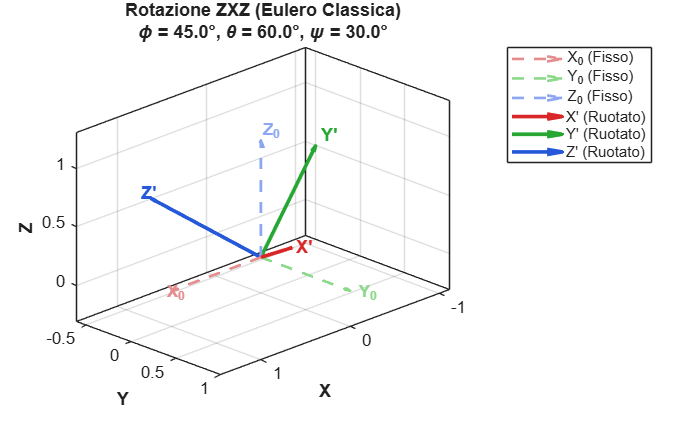

phiNum = pi/4;
thetaNum = pi/3;
psiNum = pi/6;

% Creazione Figura
figure('Name', 'Visualizzazione Rotazione ZXZ', 'Color', 'w');
hold on;
grid on;
box on;
xlabel('X', 'FontWeight', 'bold');
ylabel('Y', 'FontWeight', 'bold');
zlabel('Z', 'FontWeight', 'bold');
axis equal;
view(135, 22);

% Colori Terne: Schiariti per la fissa, Saturi per la ruotata
col_fixed_X = [0.90 0.55 0.55];
col_fixed_Y = [0.55 0.85 0.55];
col_fixed_Z = [0.55 0.65 0.95];

col_rot_X = [0.85 0.15 0.15];
col_rot_Y = [0.15 0.65 0.20];
col_rot_Z = [0.15 0.35 0.85];

% Sistema di Riferimento Fisso (Tratteggiato all'origine)
hX_0 = quiver3(0, 0, 0, 1, 0, 0, 0, 'Color', col_fixed_X, 'LineStyle', '--', 'LineWidth', 1.6);
hY_0 = quiver3(0, 0, 0, 0, 1, 0, 0, 'Color', col_fixed_Y, 'LineStyle', '--', 'LineWidth', 1.6);
hZ_0 = quiver3(0, 0, 0, 0, 0, 1, 0, 'Color', col_fixed_Z, 'LineStyle', '--', 'LineWidth', 1.6);
text(1.08, 0, 0, 'X_0', 'FontSize', 10, 'Color', col_fixed_X, 'FontWeight', 'bold');
text(0, 1.08, 0, 'Y_0', 'FontSize', 10, 'Color', col_fixed_Y, 'FontWeight', 'bold');
text(0, 0, 1.08, 'Z_0', 'FontSize', 10, 'Color', col_fixed_Z, 'FontWeight', 'bold');

% Estrazione e Disegno Assi Ruotati (ZXZ)
X_Ruotato = RZXZ_Num(:, 1);
Y_Ruotato = RZXZ_Num(:, 2);
Z_Ruotato = RZXZ_Num(:, 3);

hX_r = quiver3(0, 0, 0, X_Ruotato(1), X_Ruotato(2), X_Ruotato(3), 0, 'Color', col_rot_X, 'LineWidth', 2.2);
hY_r = quiver3(0, 0, 0, Y_Ruotato(1), Y_Ruotato(2), Y_Ruotato(3), 0, 'Color', col_rot_Y, 'LineWidth', 2.2);
hZ_r = quiver3(0, 0, 0, Z_Ruotato(1), Z_Ruotato(2), Z_Ruotato(3), 0, 'Color', col_rot_Z, 'LineWidth', 2.2);
text(X_Ruotato(1)*1.1, X_Ruotato(2)*1.1, X_Ruotato(3)*1.1, 'X''', 'FontSize', 11, 'Color', col_rot_X, 'FontWeight', 'bold');
text(Y_Ruotato(1)*1.1, Y_Ruotato(2)*1.1, Y_Ruotato(3)*1.1, 'Y''', 'FontSize', 11, 'Color', col_rot_Y, 'FontWeight', 'bold');
text(Z_Ruotato(1)*1.1, Z_Ruotato(2)*1.1, Z_Ruotato(3)*1.1, 'Z''', 'FontSize', 11, 'Color', col_rot_Z, 'FontWeight', 'bold');

title({'Rotazione ZXZ (Eulero Classica)', ...
    sprintf('\\phi = %.1f°, \\theta = %.1f°, \\psi = %.1f°', rad2deg(phiNum), rad2deg(thetaNum), rad2deg(psiNum))}, ...
    'FontSize', 11, 'FontWeight', 'bold');
legend([hX_0, hY_0, hZ_0, hX_r, hY_r, hZ_r], ...
    {'X_0 (Fisso)', 'Y_0 (Fisso)', 'Z_0 (Fisso)', 'X'' (Ruotato)', 'Y'' (Ruotato)', 'Z'' (Ruotato)'}, ...
    'Location', 'bestoutside');
hold off;

## Visualizzazione Rotazione ZXY

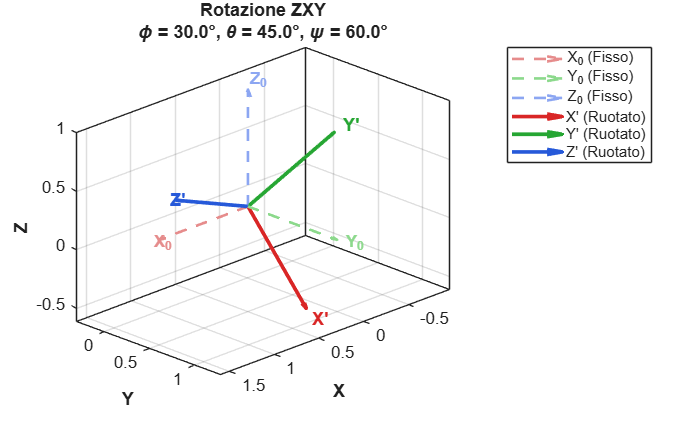

phiNum = pi/6;
thetaNum = pi/4;
psiNum = pi/3;

% Creazione Figura
figure('Name', 'Visualizzazione Rotazione ZXY', 'Color', 'w');
hold on;
grid on;
box on;
xlabel('X', 'FontWeight', 'bold');
ylabel('Y', 'FontWeight', 'bold');
zlabel('Z', 'FontWeight', 'bold');
axis equal;
view(135, 22);

% Sistema di Riferimento Fisso (Tratteggiato all'origine)
hX_0 = quiver3(0, 0, 0, 1, 0, 0, 0, 'Color', col_fixed_X, 'LineStyle', '--', 'LineWidth', 1.6);
hY_0 = quiver3(0, 0, 0, 0, 1, 0, 0, 'Color', col_fixed_Y, 'LineStyle', '--', 'LineWidth', 1.6);
hZ_0 = quiver3(0, 0, 0, 0, 0, 1, 0, 'Color', col_fixed_Z, 'LineStyle', '--', 'LineWidth', 1.6);
text(1.08, 0, 0, 'X_0', 'FontSize', 10, 'Color', col_fixed_X, 'FontWeight', 'bold');
text(0, 1.08, 0, 'Y_0', 'FontSize', 10, 'Color', col_fixed_Y, 'FontWeight', 'bold');
text(0, 0, 1.08, 'Z_0', 'FontSize', 10, 'Color', col_fixed_Z, 'FontWeight', 'bold');

% Estrazione e Disegno Assi Ruotati (ZXY)
X_Ruotato = R_ZXY_Num(:, 1);
Y_Ruotato = R_ZXY_Num(:, 2);
Z_Ruotato = R_ZXY_Num(:, 3);

hX_r = quiver3(0, 0, 0, X_Ruotato(1), X_Ruotato(2), X_Ruotato(3), 0, 'Color', col_rot_X, 'LineWidth', 2.2);
hY_r = quiver3(0, 0, 0, Y_Ruotato(1), Y_Ruotato(2), Y_Ruotato(3), 0, 'Color', col_rot_Y, 'LineWidth', 2.2);
hZ_r = quiver3(0, 0, 0, Z_Ruotato(1), Z_Ruotato(2), Z_Ruotato(3), 0, 'Color', col_rot_Z, 'LineWidth', 2.2);
text(X_Ruotato(1)*1.1, X_Ruotato(2)*1.1, X_Ruotato(3)*1.1, 'X''', 'FontSize', 11, 'Color', col_rot_X, 'FontWeight', 'bold');
text(Y_Ruotato(1)*1.1, Y_Ruotato(2)*1.1, Y_Ruotato(3)*1.1, 'Y''', 'FontSize', 11, 'Color', col_rot_Y, 'FontWeight', 'bold');
text(Z_Ruotato(1)*1.1, Z_Ruotato(2)*1.1, Z_Ruotato(3)*1.1, 'Z''', 'FontSize', 11, 'Color', col_rot_Z, 'FontWeight', 'bold');

title({'Rotazione ZXY', ...
    sprintf('\\phi = %.1f°, \\theta = %.1f°, \\psi = %.1f°', rad2deg(phiNum), rad2deg(thetaNum), rad2deg(psiNum))}, ...
    'FontSize', 11, 'FontWeight', 'bold');
legend([hX_0, hY_0, hZ_0, hX_r, hY_r, hZ_r], ...
    {'X_0 (Fisso)', 'Y_0 (Fisso)', 'Z_0 (Fisso)', 'X'' (Ruotato)', 'Y'' (Ruotato)', 'Z'' (Ruotato)'}, ...
    'Location', 'bestoutside');
hold off;

## Visualizzazione Rotazione RPY

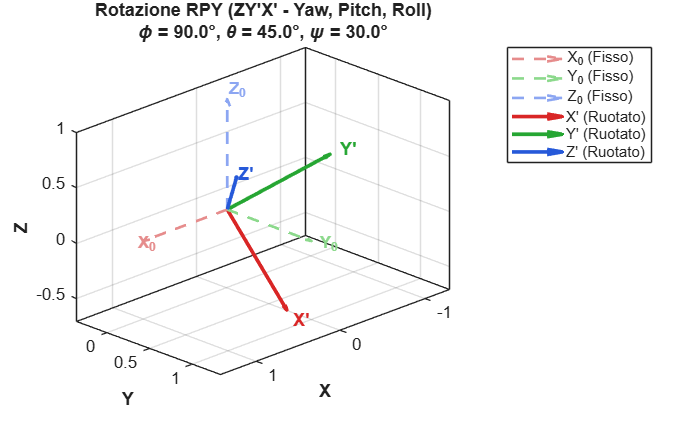

% Creazione Figura
figure('Name', 'Visualizzazione Rotazione RPY', 'Color', 'w');
hold on;
grid on;
box on;
xlabel('X', 'FontWeight', 'bold');
ylabel('Y', 'FontWeight', 'bold');
zlabel('Z', 'FontWeight', 'bold');
axis equal;
view(135, 22);

% Sistema di Riferimento Fisso (Tratteggiato all'origine)
hX_0 = quiver3(0, 0, 0, 1, 0, 0, 0, 'Color', col_fixed_X, 'LineStyle', '--', 'LineWidth', 1.6);
hY_0 = quiver3(0, 0, 0, 0, 1, 0, 0, 'Color', col_fixed_Y, 'LineStyle', '--', 'LineWidth', 1.6);
hZ_0 = quiver3(0, 0, 0, 0, 0, 1, 0, 'Color', col_fixed_Z, 'LineStyle', '--', 'LineWidth', 1.6);
text(1.08, 0, 0, 'X_0', 'FontSize', 10, 'Color', col_fixed_X, 'FontWeight', 'bold');
text(0, 1.08, 0, 'Y_0', 'FontSize', 10, 'Color', col_fixed_Y, 'FontWeight', 'bold');
text(0, 0, 1.08, 'Z_0', 'FontSize', 10, 'Color', col_fixed_Z, 'FontWeight', 'bold');

% Ripristino Angoli RPY per il Titolo
phiNum = pi/2;
thetaNum = pi/4;
psiNum = pi/6;

% Estrazione e Disegno Assi Ruotati (RPY)
X_Ruotato = R_RPY_Num(:, 1);
Y_Ruotato = R_RPY_Num(:, 2);
Z_Ruotato = R_RPY_Num(:, 3);

hX_r = quiver3(0, 0, 0, X_Ruotato(1), X_Ruotato(2), X_Ruotato(3), 0, 'Color', col_rot_X, 'LineWidth', 2.2);
hY_r = quiver3(0, 0, 0, Y_Ruotato(1), Y_Ruotato(2), Y_Ruotato(3), 0, 'Color', col_rot_Y, 'LineWidth', 2.2);
hZ_r = quiver3(0, 0, 0, Z_Ruotato(1), Z_Ruotato(2), Z_Ruotato(3), 0, 'Color', col_rot_Z, 'LineWidth', 2.2);
text(X_Ruotato(1)*1.1, X_Ruotato(2)*1.1, X_Ruotato(3)*1.1, 'X''', 'FontSize', 11, 'Color', col_rot_X, 'FontWeight', 'bold');
text(Y_Ruotato(1)*1.1, Y_Ruotato(2)*1.1, Y_Ruotato(3)*1.1, 'Y''', 'FontSize', 11, 'Color', col_rot_Y, 'FontWeight', 'bold');
text(Z_Ruotato(1)*1.1, Z_Ruotato(2)*1.1, Z_Ruotato(3)*1.1, 'Z''', 'FontSize', 11, 'Color', col_rot_Z, 'FontWeight', 'bold');

title({'Rotazione RPY (ZY''X'' - Yaw, Pitch, Roll)', ...
    sprintf('\\phi = %.1f°, \\theta = %.1f°, \\psi = %.1f°', rad2deg(phiNum), rad2deg(thetaNum), rad2deg(psiNum))}, ...
    'FontSize', 11, 'FontWeight', 'bold');
legend([hX_0, hY_0, hZ_0, hX_r, hY_r, hZ_r], ...
    {'X_0 (Fisso)', 'Y_0 (Fisso)', 'Z_0 (Fisso)', 'X'' (Ruotato)', 'Y'' (Ruotato)', 'Z'' (Ruotato)'}, ...
    'Location', 'bestoutside');
hold off;